# Exercise 4

## Modified RRT

### About This Exercise

There are many small tweaks you could make in the way trees grow from the start node to the goal. In this exercise, you will implement a few of the tweaks mentioned in the preceeding videos. The first is to make the step size of the extension step adaptable. This simple change takes into account the distance from the node we're extending to the goal and takes larger steps the further away it is. 

The second change is to make a greedy tree, where you keep extending the branch until either you hit an obstacle or the sample point you're extending towards. 

Finally, you will change the sampling strategy to bias your samples towards the goal. You can either do this by selecting the goal as your sample every so often or sample from a Gaussian centered around the goal, with normal uniform sampling mixed in.

**By the end of this exercise, you'll be able to: **

- **Modify the Rapidly-Exploring Random Tree algorithm to improve your results.**

Before making the changes to RRT, let's set up the inputs as we did previously.

lim = 4;
p1x = [-2  -1 1 2 1 -1];
p1y = [0 1 1 0 -1 -1]-1;
p2x = [-2 0 .5 -1];
p2y = [3 3 2 2];

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;

polyvec = [];
for i = 1:length(obstacle)
    obstacle(i).poly = polyshape(obstacle(i).px,obstacle(i).py);
    polyvec = [polyvec obstacle(i).poly];
end

### Adaptive Step Size

[► Complete the function RRTadaptive](matlab:open('./RRTadaptive.mlx'))

You'll notice that it is empty. First copy over all of the code from your working RRT function, then alter it to have an adaptive step size. Simply scale the dq by the distance between the node you're extending and the goal and have that be your step size.

Once the function is ready, specify the inputs to RRT. Set dq appropriately (you might have to try a few values), and then run RRTadaptive.

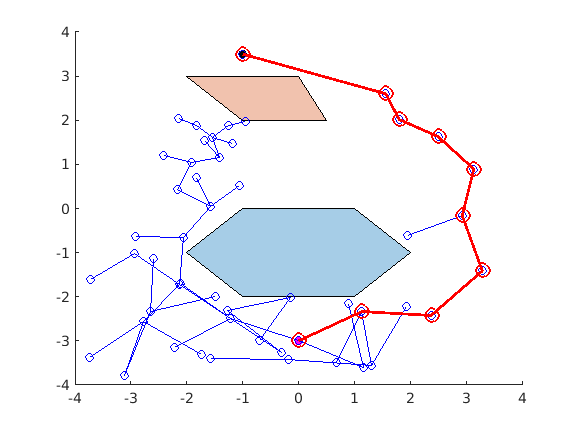

start = [-0, -3];
goal = [-1, 3.5];
dq = 0.2;
N = 150;
nodex_xy = RRTadaptive(start, goal, polyvec, lim, N, dq, 1);

### Greedy RRT

Instead of moving a certain step size towards a sample point, the greedy RRT will keep stepping towards that sample point until it either reaches it or hits an obstacle.

[► Complete the RRTgreedy function](matlab:open('./RRTgreedy.mlx')), where you can copy your previous RRT and update the tree extension step. Here, the step size just determines how close to an obstacle you want to get.

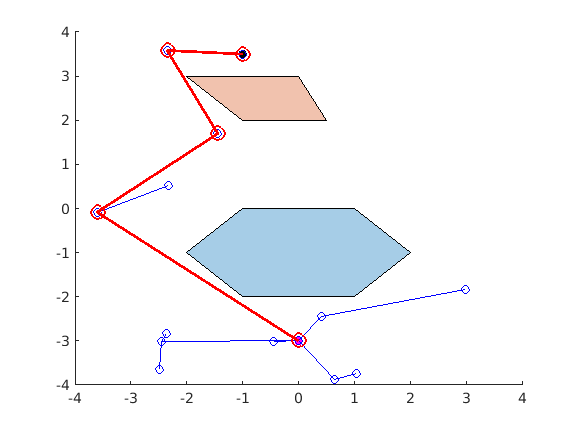

dq = 0.7;
nodex_xy = RRTgreedy(start, goal, polyvec, lim, N, dq, 1);

### Biased RRT

Finally, since we want to get to the goal, why not bias our samples towards it instead of being truly random. It is up to you how to bias, but we recommend alternating samples between using a Gaussian with a mean at the goal and the previous uniform sampling. 

[► Complete the RRTbiased function](matlab:open('./RRTbiased.mlx')), where again you'll copy the code from RRT and update the sampling step.

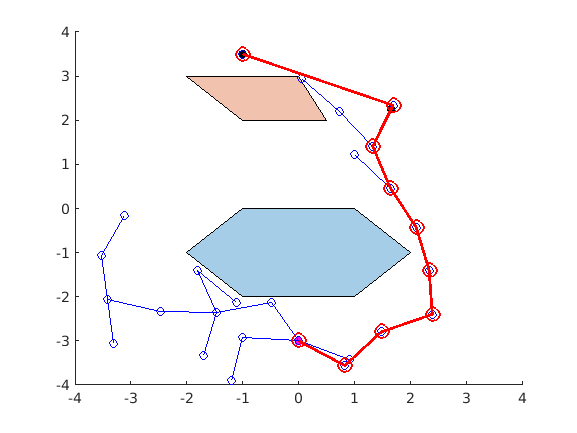

dq = 1;
nodex_xy = RRTbiased(start, goal, polyvec, lim, N, dq, 1);

### Finished!

As you can see, changing the algorithm slightly can result in different behaviors, which may be beneficial depending on the scenario. Also, we split up these changes to be different functions for simplicity, but it would be better to include all of these options into a single RRT function. Finally, for an extra challenge, you can try to create what is called a bidirectional RRT, or BiRRT, which extends trees from both the start and the goal and terminates when the two trees can see each other. Your final project for this course will be to use RRT to do motion planning on the robot in the simulator.